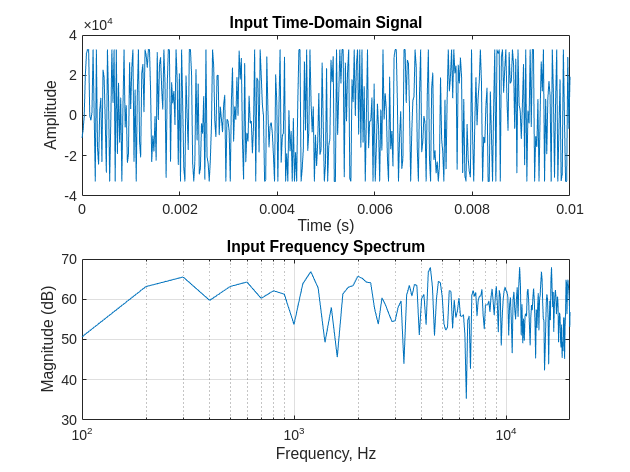

% Load the WAV file
[in, fs] = audioread('in_white_noise_10ms.wav', 'native'); % signal is the audio data, fs is the sample rate

% Plot the time-domain signal
t = (0:length(in)-1) / fs;
figure;
subplot(2,1,1);
plot(t, in);
xlabel('Time (s)');
ylabel('Amplitude');
title('Input Time-Domain Signal');

% Compute and plot the spectrum with log frequency axis
n = length(in);
frequencies = (0:n-1) * (fs/n); 
in_zp = [zeros([256,1]); in; zeros([256,1])];
spectrum = fft(in_zp);
magnitude_dB = 20 * log10(abs(spectrum) / n); % Magnitude in dB

% Plot using a logarithmic frequency axis
subplot(2,1,2);
semilogx(frequencies(1:floor(n/2)), magnitude_dB(1:floor(n/2)));
xlim([0,20000]);
xlabel('Frequency, Hz');
ylabel('Magnitude (dB)');
title('Input Frequency Spectrum');
grid;

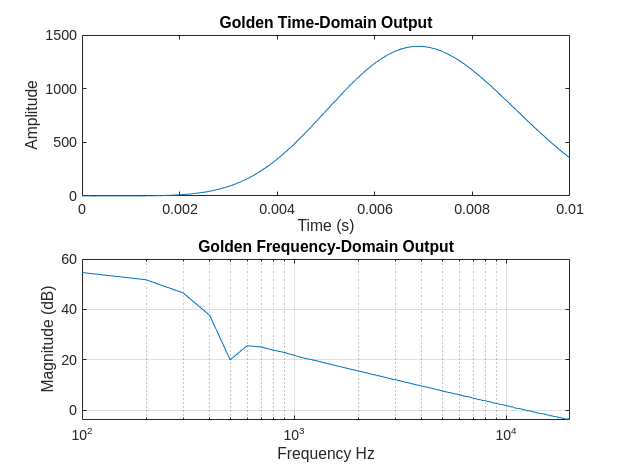

% ---------- GOLDEN ----------
% Load the WAV file
[out_golden, fs] = audioread('golden_output.wav', 'native'); % signal is the audio data, fs is the sample rate

% Plot the time-domain signal
t = (0:length(out_golden)-1) / fs;
figure;
subplot(2,1,1);
plot(t, out_golden);
xlabel('Time (s)');
ylabel('Amplitude');
title('Golden Time-Domain Output');

% Compute and plot the spectrum with log frequency axis
n = length(out_golden);
frequencies = (0:n-1) * (fs/n); 
out_golden_zp = [zeros([256,1]); out_golden; zeros([256,1])];
spectrum = fft(out_golden_zp);
magnitude_dB = 20 * log10(abs(spectrum) / n); % Magnitude in dB

% Plot using a logarithmic frequency axis
subplot(2,1,2);
semilogx(frequencies(1:floor(n/2)), magnitude_dB(1:floor(n/2)));
xlim([0,20000]);
xlabel('Frequency Hz');
ylabel('Magnitude (dB)');
title('Golden Frequency-Domain Output');
grid;

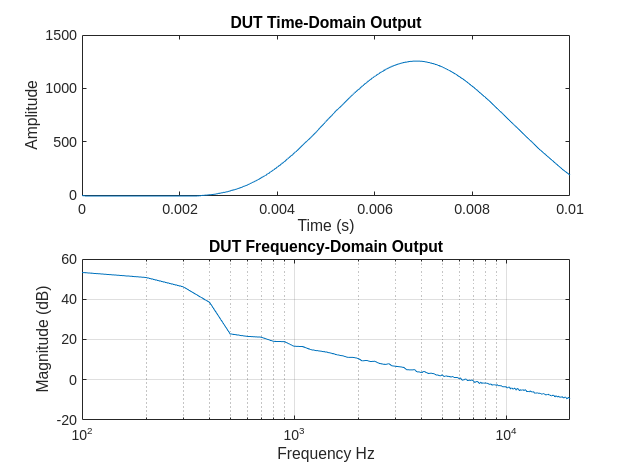

% ---------- DUT ----------
% Load the WAV file
[out_dut, fs] = audioread('out.wav', 'native'); % signal is the audio data, fs is the sample rate

% Plot the time-domain signal
t = (0:length(out_dut)-1) / fs;
figure;
subplot(2,1,1);
plot(t, out_dut);
xlabel('Time (s)');
ylabel('Amplitude');
title('DUT Time-Domain Output');

% Compute and plot the spectrum with log frequency axis
n = length(out_dut);
frequencies = (0:n-1) * (fs/n); 
out_dut_zp = [zeros([256,1]); out_dut; zeros([256,1])];
spectrum = fft(out_dut_zp);
magnitude_dB = 20 * log10(abs(spectrum) / n); % Magnitude in dB

% Plot using a logarithmic frequency axis
subplot(2,1,2);
semilogx(frequencies(1:floor(n/2)), magnitude_dB(1:floor(n/2)));
xlim([0,20000]);
xlabel('Frequency Hz');
ylabel('Magnitude (dB)');
title('DUT Frequency-Domain Output');
grid;

currdata = typecast(0x000013CD, 'int32')

currdata = int32
5069

prevdata = typecast(0x00000000, 'int32');
decay = 512;
data_o = currdata + bitshift(decay*(prevdata - currdata), -10,"int32")

data_o = int32
2534

data_o_hex = dec2hex(data_o)

data_o_hex = '9E6'

data_o_bin = dec2bin(data_o,16)

data_o_bin = '0000100111100110'


received = 0x00

received = uint8
0

sum(out_golden - out_dut)

ans = 40264